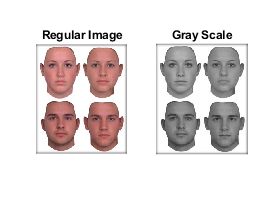



clear all;
clc

% Step 1
% ------------------------
img1 = importdata('image2.jpg');
% image(img);
prompt = 'Enter the size of the window.(e.g. 5,7 or 9) : ';
window_size = input(prompt);

prompt = 'Enter the roundness threshold value.(Between 0 and 1) : ';
Rnd_Thresh = input(prompt);

prompt = 'Enter the weight threshold value.(e.g. 0.5, 0.7 0r 0.9) : ';
Weight_Thresh = input(prompt);



%Change to gray values
img_gray = rgb2gray(img1);

figure
subplot(1,2,1)
imshow(img1), title('Regular Image')
subplot(1,2,2)
imshow(img_gray), title('Gray Scale') 

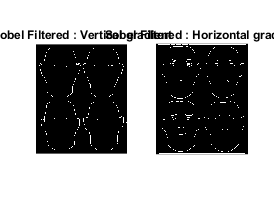


% Get the bounds of the image matrix 
row_height = size(img_gray, 1);
col_width = size(img_gray, 2);

%Creating zero matrices to hold roundness and weight values
rnd_mat = zeros(row_height, col_width);
wght_mat = zeros(row_height, col_width);

border_pix = floor(window_size/2);


% Step 2
% ------------------------
% Detect edges using the Sobel operator
Grad_vert = edge(img_gray,'Sobel', [],'vertical');    % vertical gradient
Grad_horz = edge(img_gray,'Sobel', [],'horizontal');    % vertical gradient    
figure
subplot(1,2,1)
imshow(Grad_vert), title('Sobel Filtered : Vertical gradient')
subplot(1,2,2)
imshow(Grad_horz), title('Sobel Filtered : Horizontal gradient') 

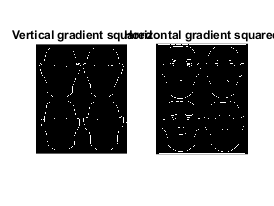


% Square the gradient values 
grad_vert2 = Grad_vert.^2;
grad_horz2 = Grad_horz.^2;
figure
subplot(1,2,1)
imshow(grad_vert2), title('Vertical gradient squared')
subplot(1,2,2)
imshow(grad_horz2), title('Horizontal gradient squared')

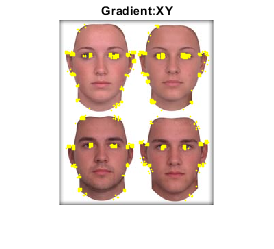


% Multiplication of gradients in x and y direction 
gradXY = Grad_horz.*Grad_vert;
figure
subplot(1,1,1)
imshow(img1), title('Gradient:XY')


% Solve for the normal matrix for each pixel
for i = 1:row_height
    for j = 1:col_width
            % Default all the matrix values to zero
            error_ellipse_rnd(i,j) = 0;                     
            error_ellipse_weight(i,j) = 0;
        
        if (((i >= border_pix + 1) && (i <= (row_height-border_pix))) && (j >= (border_pix + 1) && (j <= (col_width-border_pix))))
            
            % fetch the values from the windows current position from the image matrix in vertical direction
            Moving_window_val_vert = grad_vert2(i - border_pix: i + border_pix, j- border_pix: j + border_pix);  
            sum_total_vert = sum(sum(Moving_window_val_vert));
            
            % fetch the values from the windows current position from the image matrix in horizontal direction
            moving_window_values_horz = grad_horz2(i - border_pix: i + border_pix, j- border_pix: j + border_pix);  
            sum_total_horz = sum(sum(moving_window_values_horz));
            
            % fetch the values from the windows current position from the image matrix in horizontal direction
            moving_window_values_XY = gradXY(i - border_pix: i + border_pix, j- border_pix: j + border_pix);  
            sum_total_XY = sum(sum(moving_window_values_XY));
            
            % Now we formulate the N matrix elements
            N_matrix = [sum_total_vert, sum_total_XY; sum_total_XY, sum_total_horz];
            % determinant =(N11 * N22) - (N21 * N12) as expressed below
             %determinant = (N_matrix(1)*N_matrix(4)) - (N_matrix(2)*N_matrix(3));
            
            % Solve for Roundness and Weight matrix
             %roundness(i,j) = (4*determinant) / ((trace(N_matrix))^2);    
             %weight(i,j) = determinant/(trace(N_matrix)); 
            %trace is the sum of the diagonal elements of the N matrix
            %determine the eigen values of the N Matrix to compute roundness and weight
            eigen_val = eig(N_matrix);
            lambda1 = eigen_val(1);
            lambda2 = eigen_val(2);
            
            % Solve for error of ellipse for Roundness and Weight matrix. %errell or error of ellipse values shows the pairwise correlation between the two values image spatial dimension 
            error_ellipse_rnd(i,j) = (lambda1*lambda2)/(lambda1+lambda2);    
            error_ellipse_weight(i,j) = 1 -((lambda1-lambda2)/(lambda1+lambda2))^2; 
            
            
            % Run each matrix value against threshold values 
            if (error_ellipse_weight(i,j) > Weight_Thresh && error_ellipse_rnd(i,j) > Rnd_Thresh)
                hold on; %hold is a method that retains the current plot when adding new plots
                plot(j,i,'y+','MarkerSize',0.5)  
            end
        end
    end
end